### Plotting Fig.S3: Time-scale comparision between the dipolar Hamiltonian and the Floquet Hamiltonian

Code last modified  by Yuchen Li, 2023-10-20

clear;clc

S.mat: the first line is the observable value for Floquet driving, and the second line is the one for free evolution

S_uncert.mat: the errorbar of S, extracted from the FID

load S.mat
load S_uncert.mat

figure()
J=2*pi*1460; %average value of J, see Fig.S1
tau=5*1e-6; %in us, average pulse interval of the rf sequence

quench_time_seq1=24*tau*(0:40); %one period of Floquet driving is 24*tau. There are 0:40 cycles
quench_time_seq2=12*1e-6*(0:40);%the sampling interval of free evolution is 12 us.

x1=quench_time_seq1*J;
x2=quench_time_seq2*J;

y1=S(1,:);
y2=S(2,:);
y1_uncert=FID_uncertainty(1,:);
y2_uncert=FID_uncertainty(2,:);

[fitresult1, ~] = interpolate(x1, y1); %interpolation
[fitresult2, ~] = interpolate(x2, y2);


c0 = 1;
[c,c_errorbar]=fit_c(fitresult1,x2,y2,c0) %Rescale the time scale to collapse the two curves, c--scaling factor


找到局部最小值。

优化已完成，因为梯度大小小于
函数容差的 1e-4 倍。

<停止条件详细信息>


c = 0.9917

c_errorbar = 0.0062

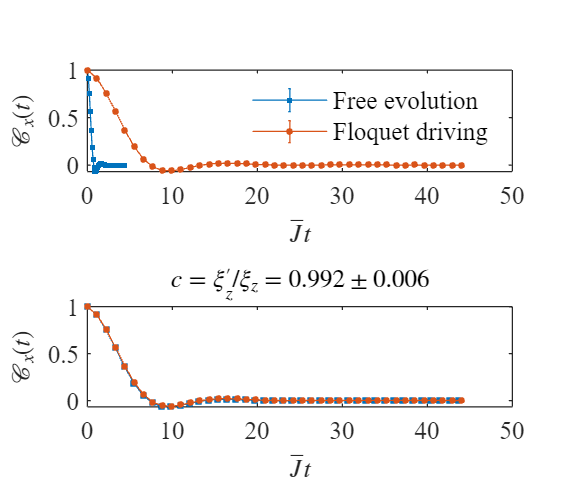


figure()
color={'#0072bd','#D95319','#eDb120','#7e2f8e','#77ac30'};
marker={'.-','-s','-s','-d'};
markersize=[8,2,2,2,2];

subplot(2,1,1)
errorbar(x2,y2,y2_uncert,marker{2},'markersize',markersize(2),'MarkerFaceColor',color{1},'color',color{1},'CapSize',1)
hold on
errorbar(x1,y1,y1_uncert,marker{1},'markersize',markersize(1),'MarkerFaceColor',color{2},'color',color{2},'CapSize',1)
xlabel('$\bar{J}t$','Interpreter',"latex")
ylabel('$\mathcal{C}_x(t)$','Interpreter',"latex")
legend('Free evolution','Floquet driving','box','off')

subplot(2,1,2)
markersize=[8,3,2,2,2];
errorbar(x2*c*10,y2,y2_uncert,marker{2},'markersize',markersize(2),'MarkerFaceColor',color{1},'color',color{1},'CapSize',1)
hold on
errorbar(x1,y1,y1_uncert,marker{1},'markersize',markersize(1),'MarkerFaceColor',color{2},'color',color{2},'CapSize',1)
xlabel('$\bar{J}t$','Interpreter',"latex")
ylabel('$\mathcal{C}_x(t)$','Interpreter',"latex")
% legend('Free evolution','Floquet driving','box','off')
title(['$c=\xi_z''/\xi_z=',num2str(round(c,3)),'\pm',num2str(round(c_errorbar,3)),'$'],'Interpreter','latex')
fontname(gcf,"Times New Roman")
fontsize(gcf,10,'points')
set(gcf,'unit','centimeters','position',[10,10,8,7]);

function [fitresult, gof] = interpolate(x, y)
[xData, yData] = prepareCurveData( x, y );
ft = 'linearinterp';
opts = fitoptions( 'Method', 'LinearInterpolant' );
opts.ExtrapolationMethod = 'linear';
opts.Normalize = 'on';
[fitresult, gof] = fit( xData, yData, ft, opts );
end

function [c,c_errorbar]=fit_c(fitresult2,x1,y1,c0)

% options = optimoptions('lsqcurvefit','Algorithm','levenberg-marquardt');
% fun = @(cc)(fitresult2(x1*cc)-y1);
% c0 = 0.1;
% [c,resnorm,residual,~,~,~,jacobian]= lsqnonlin(fun,c0,[],[],options);

fun = @(c,x)fitresult2(x*10/c); %the scaling factor c'=xi_z^dip/xi_z'=10/c, where c=xi_z'/xi_z is to be calibrated.
options = optimoptions('lsqcurvefit','Algorithm','levenberg-marquardt');
[c,resnorm,residual,~,~,~,jacobian]= lsqcurvefit(fun,c0,x1,y1',[],[],options);

p=0.95;
nu=length(x1)-1;
% pLo = (1-p)/2;
pUp = 1 - (1-p)/2;
alpha = tinv(pUp, nu);
c_errorbar=alpha*sqrt(diag((jacobian'*jacobian)^(-1)))*sqrt(resnorm/nu);
% c_errorbar =nlparci(c,residual,'Jacobian',jacobian)
end